% Fine Estimate of Carrier Frequency Offset
% Create non-HT configuration object.
vht = wlanVHTConfig;
vht.ChannelBandwidth = 'CBW20';
vht.MCS = 8;
% Generate a non-HT waveform.
txSig = wlanWaveformGenerator([1;0;0;1],vht);
% [y_Lsig,bits_Lsig] = wlanLSIG(vht);
% [y_vhtsiga,bits_vhtsiga] = wlanVHTSIGA(vht);
% [y_vhtsigb,bits_vhtsigb] = wlanVHTSIGB(vht);

% Create a phase and frequency offset object and introduce a 2 Hz frequency offset.
tgacChan = wlanTGacChannel('SampleRate',20e6,'ChannelBandwidth','CBW20','DelayProfile','Model-E');

chNoise = comm.AWGNChannel('NoiseMethod','Signal to noise ratio (SNR)',...
    'SNR',30);
pfOffset = comm.PhaseFrequencyOffset('SampleRate',20e6,'FrequencyOffset',3000);
rxSig = chNoise(tgacChan(txSig));
rxSig = pfOffset(rxSig);

% Extract the L-STF and estimate the frequency offset.
ind_STF = wlanFieldIndices(vht,'L-STF');
rxlstf = rxSig(ind_STF(1):ind_STF(2),:);
% rxlstf_origin = txSig(ind_STF(1):ind_STF(2),:);
% cp_stf = zeros(32,2);
% cp_stf(:,1) = rxlstf_origin(129:160);
% cp_stf(:,2) = rxlstf_origin(1:32);
% freqOffsetEst = wlanCoarseCFOEstimate(rxlstf,'CBW20')

% Extract the L-LTF and estimate the frequency offset.
ind_LTF = wlanFieldIndices(vht,'L-LTF');
rxlltf = rxSig(ind_LTF(1):ind_LTF(2),:);
% rxlltf_origin = txSig(ind_LTF(1):ind_LTF(2),:);
% isequal(rxlltf_origin(129:160),rxlltf_origin(1:32))
% freqOffsetEst_ = wlanFineCFOEstimate(rxlltf,'CBW20')

% Coarse CFO Estimation
first_STF = rxlstf(33:96);
second_STF = rxlstf(97:160);
Ts = 1/20000000;
phase_STF = 1/16 * angle(rxlstf(33:144)'*rxlstf(49:160))

phase_STF = 0.0010

CFO_STF = phase_STF/2/pi/Ts

CFO_STF = 3.1967e+03

%% Fine CFO Correlation
first_LTF = rxlltf(33:96);
second_LTF = rxlltf(97:160);
Ts = 1/20000000;
phase_LTF = 1/64 * angle(first_LTF'*second_LTF)

phase_LTF = 9.6014e-04

CFO_LTF = phase_LTF/2/pi/Ts

CFO_LTF = 3.0562e+03

% Fine CFO Correlation
mm = 0:127;
mm = mm';
rexlltf_af_cor = rxlltf(33:160) .* exp(-j*mm*phase_STF);
phase_LTF = 1/64 * angle(rexlltf_af_cor(1:64)'*rexlltf_af_cor(65:128));
CFO_STF_LTF = (phase_LTF+phase_STF)/2/pi/Ts

CFO_STF_LTF = 3.0562e+03

% LTF   FFT 
first_LTF = rxlltf(33:96);
second_LTF = rxlltf(97:160);

k2 = 1:1:64;
k2 = k2';
LTFfft = zeros(64,2);

for kk = 1:64       
        yy =  sqrt(52) *first_LTF .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        LTFfft(kk,1) = 1/64 *  sum(yy) ;
end

for kk = 1:64       
        yy =  sqrt(52) *second_LTF .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        LTFfft(kk,2) = 1/64 *  sum(yy) ;
end

LTF_52(:,:) = [LTFfft(7:32,:);LTFfft(34:59,:)];

%% Channel gain H (ZZF)
seqLong = [1;1;-1;-1;1;1;-1;1;-1;1;1;1;1;1;1;
            -1;-1;1;1;-1;1;-1;1;1;1;1;1;-1;-1;1;
            1;-1;1;-1;1;-1;-1;-1;-1;-1;1;1;-1;-1;1;-1;
            1;-1;1;1;1;1];
H = (LTF_52(:,1)+LTF_52(:,2))/2 .* seqLong;

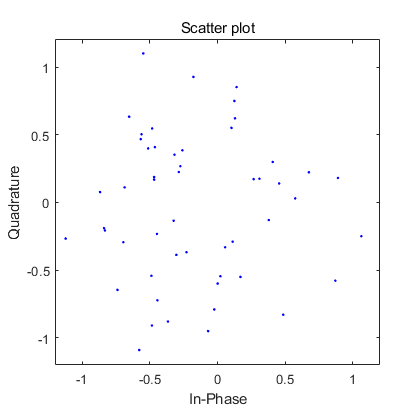

%% L-SIG FFT 
ind_LSIG = wlanFieldIndices(vht,'L-SIG');
rxLLSIG = rxSig(ind_LSIG(1):ind_LSIG(2),:);

% mm = 128:207;
mm = 100:179;

mm = mm';

rexlsig_af_cor = rxLLSIG .* exp(-j*mm*phase_LTF);
% rexlsig_af_cor = rxLLSIG(17:80);
k2 = 1:1:64;
k2 = k2';
lsigfft = zeros(64,1);

for kk = 1:64       
        yy =  sqrt(52) * rexlsig_af_cor(17:80) .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        lsigfft(kk) = 1/64 *  sum(yy) ;
end
LSIG_52 = [lsigfft(7:32,:);lsigfft(34:59,:)];
scatterplot(LSIG_52)

% Residual Frequency Offset Correlation
pilot = [lsigfft(12);lsigfft(26);lsigfft(40);lsigfft(54)];
H_pilot = [H(6);H(20);H(33);H(47)];
P_ = [1;1;1;-1];
residual_offset = angle(pilot'*(H_pilot.*P_))

residual_offset = -0.0908

CFO_pilot = residual_offset/2/pi/Ts

CFO_pilot = -2.8891e+05

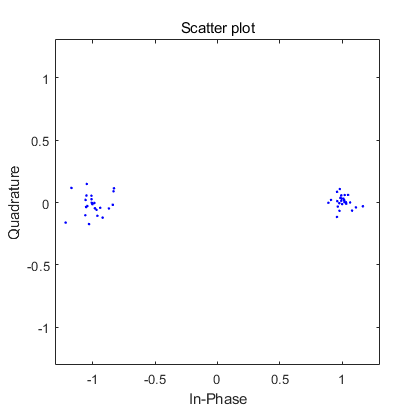


final_lsig = LSIG_52./H *exp(j*residual_offset);
% final_lsig = LSIG_52./H ; 

scatterplot(final_lsig)

% Extract 48 data bits
BF_mod = [LTFfft(7:11);LTFfft(13:25);LTFfft(27:32);LTFfft(34:39);LTFfft(41:53);LTFfft(55:59)];

다음 사용 중 오류가 발생함: vertcat
결합하려는 배열의 차원이 일치하지 않습니다.

% Constellation Demapper 
% numBPSCS = 1; % Number of coded bits per subcarrier per spatial stream
% phase = [0 pi/2]; % BPSK and QBPSK
% noiseVar = 0;
demappedData = wlanConstellationDemap(BF_mod,0,numBPSCS,phase);
demappedBits = (demappedData<=0);

% BCC Deinterleaver
number_CBPSSI = 48; % number of coded bits per OFDM symbol per spatial stream per interleaver block
cbw = 'CBW20';

full_demap = double(demappedBits);

% isequal(out,full_demap)

deinterleave = wlanBCCDeinterleave(full_demap,'Non-HT',number_CBPSSI,cbw);
size(deinterleave)
isequal(bcc_encodedData,deinterleave)

% VHT-SIGA   FFT 
ind_VHTSIG = wlanFieldIndices(vht,'VHT-SIG-A');
rxVHTSIG = rxSig(ind_VHTSIG(1):ind_VHTSIG(2),:);
first_LTF = rxVHTSIG(17:80);
second_LTF = rxVHTSIG(97:160);

k2 = 1:1:64;
k2 = k2';
VHT_SIGAfft = zeros(64,2);

for kk = 1:64       
        yy =  sqrt(52) *first_LTF .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        VHT_SIGAfft(kk,1) = 1/64 *  sum(yy) ;
end

for kk = 1:64       
        yy =  sqrt(52) *second_LTF .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        VHT_SIGAfft(kk,2) = 1/64 *  sum(yy) ;
end

% VHT-DATA FFT 
ind_DATA = wlanFieldIndices(vht,'VHT-Data');
rxVHTDATA = rxSig(ind_DATA(1):ind_DATA(2),:);
n=8
vhtdata_remove_cp = rxVHTDATA(n*80+17:(n+1)*80);

k2 = 1:1:64;
k2 = k2';
VHTDatafft = zeros(64,1);

for kk = 1:64       
        yy =  sqrt(56) * vhtdata_remove_cp .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        VHTDatafft(kk) = 1/64 *  sum(yy) ;
end
